# Romberg-Quadratur

Wir untersuchen die Romberg Extrapolation angewandt auf die summierte Trapezregel, zur Annäherung eines Integrals   $I=\int_0^1 f(x)\, dx$. 

Sei 

     $T(h)=h\big[\frac12 f(0) +f(t_1)+\ldots+f(t_{n-1})+\frac12 f(1)\big]$ , mit $t_j=jh$, $h=1/n$,

die summierte Trapezregel, und $T_{i,0}:=T(2^{-i}h_0)$, $i=0,\ldots,6$, mit $h_0:=0.25$. Ausgehend von diesen 7 Approximationen des Integrals $I$ wird ein  Romberg-Schema berechnet (siehe Buch):

                
$$T_{i,j}:=\frac{4^j T_{i,j-1}-T_{i-1,j-1}}{4^j-1},\quad 1 \leq j  \leq i \leq 6.$$


Als Beispiele betrachten wir:

    1.   $f(x)=0.25\pi^2 x\cos(0.5 \pi x)+0.5\pi e^{0.5\pi x}$    (Beispiel Buch umskaliert auf $[0,1]$)

    2.   $f(x)= x e^x$      (glatte Funktion)

    3.  $f(x)= \sqrt{x}$       (nicht glatt an der Stelle $x=0$)

 Für diese Bespiele kann  analytisch der exakte Wert des Integrals $I$ berechnet werden.

 Durch Angabe von **choice** $\in \{1,2,3\}$ wird eins dieser Bespiele gewählt. 

choice=2

choice = 2

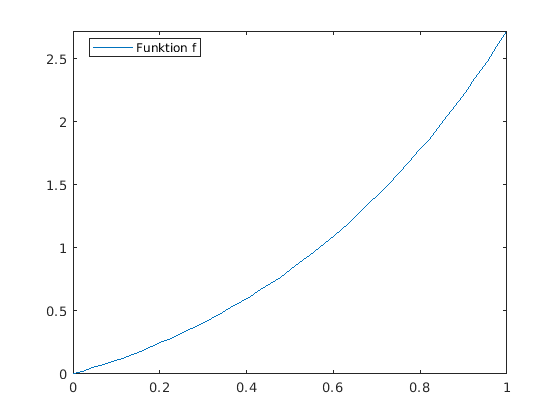

[f,Iexakt]= Beispiel(choice);
fplot(f,[0 1]);
legend('Funktion f', 'Location','best');

Die Trapezsummen $T_{i,0}$ und zugehörige Fehler $|T_{i,0}-I|$, $i=0,\ldots,6$, werden berechnet und gezeigt.

Ausgehend von diesem Approximationen werden die Romberg-Approximationen $T_{i,j}$ und entsprechende Fehler $|T_{i,j}-I|$ berechnet.

# Aktivität:

Sie können den Parameter** choice** variieren. Beobachten Sie das Fehlerverhalten im Romberg-Schema. Weshalb liefert das Romberg-Schema für das Beispiel **choice**=3 keine (signifikant) genaueren Approximationen?

kmax=7;
Trapezsumme=zeros(kmax,1);
for k=1:kmax
    n=2^(k+1);
    h=1/n;
    T= 0.5*(f(0) + f(1));
    for i=1:n-1
        T= T + f(i*h);
    end
    Trapezsumme(k)=h*T;
end 
fprintf('\nErgebnisse der summierten Trapezregel:\n');


Ergebnisse der summierten Trapezregel:


format long;
Trapezsumme

Trapezsumme =    1.023064479052757
   1.005774107367820
   1.001444027067707
   1.000361038046700
   1.000090261466905
   1.000022565488932
   1.000005641379871


format shorte;
Fehler= abs(Trapezsumme - Iexakt)

Fehler =    2.3064e-02
   5.7741e-03
   1.4440e-03
   3.6104e-04
   9.0261e-05
   2.2565e-05
   5.6414e-06


format long;
disp('----------------');

----------------


fprintf('\nRomberg-Schema:\n');


Romberg-Schema:


T= extrapolation(Trapezsumme)

T =    1.023064479052757                 NaN                 NaN                 NaN                 NaN                 NaN                 NaN
   1.005774107367820   1.000010650139507                 NaN                 NaN                 NaN                 NaN                 NaN
   1.001444027067707   1.000000666967670   1.000000001422881                 NaN                 NaN                 NaN                 NaN
   1.000361038046700   1.000000041706364   1.000000000022277   1.000000000000045                 NaN                 NaN                 NaN
   1.000090261466905   1.000000002606974   1.000000000000348   1.000000000000000   1.000000000000000                 NaN                 NaN
   1.000022565488932   1.000000000162941   1.000000000000006   1.000000000000000   1.000000000000000   1.000000000000000                 NaN
   1.000005641379871   1.000000000010184   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000   1.000000000000000


fprintf('\nGenauigkeit der Approximationen im Romberg-Schema:\n');


Genauigkeit der Approximationen im Romberg-Schema:


format shorte;
Fehler= Error(T,Iexakt)

Fehler =    2.3064e-02          NaN          NaN          NaN          NaN          NaN          NaN
   5.7741e-03   1.0650e-05          NaN          NaN          NaN          NaN          NaN
   1.4440e-03   6.6697e-07   1.4229e-09          NaN          NaN          NaN          NaN
   3.6104e-04   4.1706e-08   2.2277e-11   4.5075e-14          NaN          NaN          NaN
   9.0261e-05   2.6070e-09   3.4794e-13   1.1102e-16   3.3307e-16          NaN          NaN
   2.2565e-05   1.6294e-10   5.5511e-15   2.2204e-16   2.2204e-16   2.2204e-16          NaN
   5.6414e-06   1.0184e-11   2.2204e-16   2.2204e-16   2.2204e-16   2.2204e-16   2.2204e-16


function [f,Iexakt]= Beispiel(bsp)
switch bsp
    case 1
        f= @(x) 0.25*pi^2*x.*cos(0.5*pi.*x) + 0.5*pi*exp(0.5*pi.*x);
        Iexakt= pi/2 + exp(0.5*pi) - 2;
    case 2
        f= @(x) x.*exp(x);
        Iexakt= 1;
    case 3
        f= @(x) sqrt(x);
        Iexakt= 2/3;
end

end
 
 
function T=extrapolation(t)
    m=length(t);
    T=NaN*zeros(m,m);
    T(:,1)=t;
    for j=2:m
        for i=j:m
            T(i,j)= (4^(j-1)*T(i,j-1) - T(i-1,j-1))/(4^(j-1)-1);
        end
    end
end


function F=Error(T,Iexakt)
    m=length(T);
    F=NaN*zeros(m,m);
    for j=1:m
        for i=j:m
            F(i,j)= abs(T(i,j) - Iexakt);
        end
    end
end
 
     